## GBP package tutorial

2024 May

Yiping Wang, Natasha Sachdeva, Sharika Saraf

**version: **cpu

#### 0. Change MATLAB path to "...\***GBP_matlab_v1.2"***

load('init_GBP'); % load unit convention
colormap jet;

#### 1. Basic setup for beam propagation with optical element

Define simulation area and sampling rate (choices are made empirically in combination of limitation requried by different propagator, see Propagators)

size = 8*w0; % size of the grid (simulation window)
N = 2^10-1; % number (NxN) of grid pixels

Initialize a Gaussian laser beam

w0 = 0.6*mm;  % laser beam width
wavelength = 688*nm; % wavelength
F0 = GaussianBeam(1,w0,wavelength,0*mm,0*mm,0,0,0,size,N);

plot intensity and phase profile of the beam we just initialized

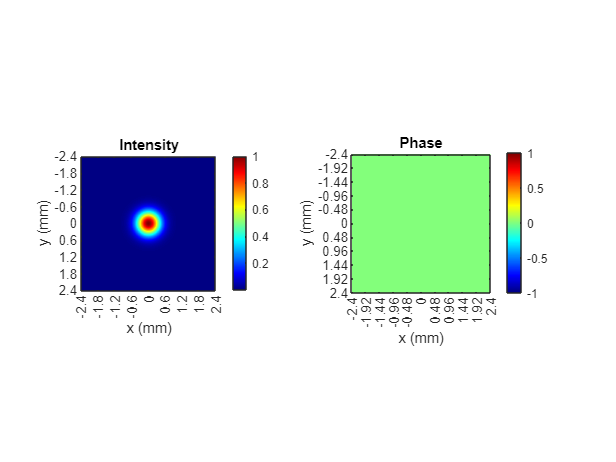

figure;
plot2(F0)

Free space propagation of the laser beam

F = Fresnel(F0,10*cm);

***BEAM PROPAGATION USING 'Fresnel'***


Now, we introduce a telescope. The laser would go through one lens of focal length *f1*, free propagate for *f1 + f2, * and go through a second lens *f2*

f1 = 25.4*mm;
f2 = 75*mm;
% 1st lens
F = ThinLens(f1,0,0,F);
% free propagate for f1+f2
F = Fresnel(F,f1+f2);

***BEAM PROPAGATION USING 'Fresnel'***


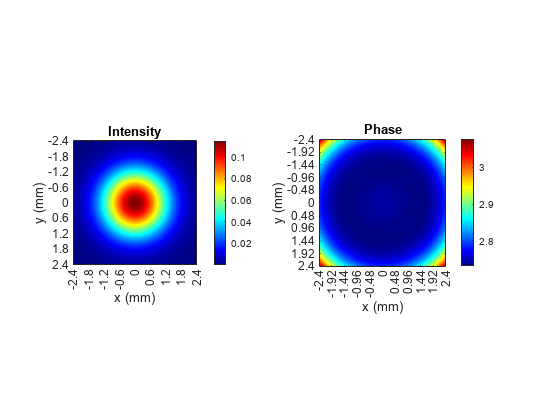

% second lens
F = ThinLens(f2,0,0,F);
figure;
plot2(F)

#### 2. Calibrate laser wavefront aberration with Mach Zender optical interferometer

In this expample we introduce aberration (edge clipping) to *arml* of the Mach Zender interferometer. A phase shear, or a tilt angle, is introduced to *armr* before the two beam recombine. We then combine *arml *and *armr*, and look at the interference between the two beams.

size = 8*w0; % size of the grid (simulation window)
N = 2^10-1; % number (NxN) of grid pixels

%% initialize the Gaussian laser beam for MZ 
w0 = 0.6*mm;  % laser beam width
wavelength = 688*nm; % wavelength
F0 = GaussianBeam(1,w0,wavelength,0*mm,0*mm,0,0,0,size,N);

Right arm (non-aberrationed), with phase shear

% before final mirror(phase shear)
dist_r1 = 0.2;
% final mirro to obervation point
dist_r2 = 0.2+0.05;

shear_angle = 2.5e-3;

Fr = Fresnel(F0,dist_r1);

***BEAM PROPAGATION USING 'Fresnel'***



Fr = PhaseShearX(shear_angle,Fr);

Fr = Fresnel(Fr,dist_r2);

***BEAM PROPAGATION USING 'Fresnel'***


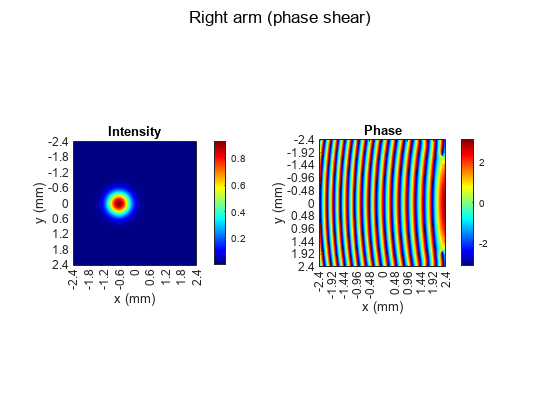

figure;
plot2(Fr)
sgtitle("Right arm (phase shear)")

Left arm (aberrated)

% before aberration
dist_l1 = 0.1;
% from aberration to observation point(camera)
dist_l2 = 0.3+0.05;

Fl = Fresnel(F0,dist_l1);

***BEAM PROPAGATION USING 'Fresnel'***



offset = -0.8; % clipped ratio
Fl = crop(offset*w0,Fl);

Fl = Fresnel(Fl,dist_l2);

***BEAM PROPAGATION USING 'Fresnel'***


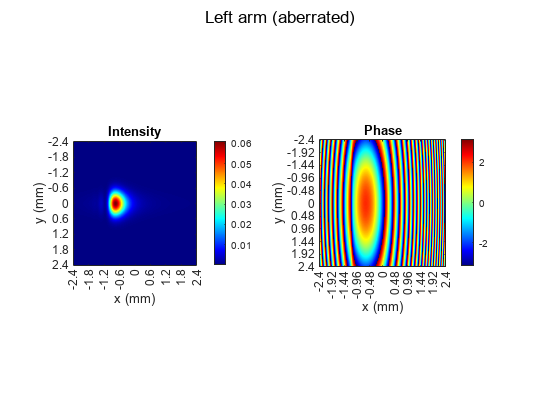

figure;
plot2(Fl)
sgtitle("Left arm (aberrated)")

Now we mix the two beams and let them interfere

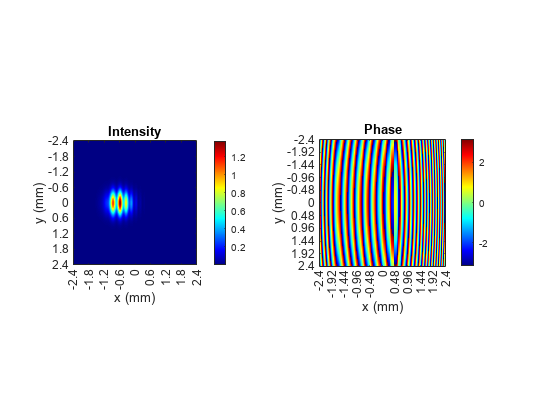

F_mix = BeamMix(Fl,Fr);
figure;
plot2(F_mix)